# PD2.2 Sensor Measurement Tutorial

The purpouse of this circuit is to behave like a **theremin**. A **theremin** is an electronic musical instrument controlled without physical contact by the performer. **Theremins** sense the relative position of the hands and control oscillators for frequency with one hand.

#### 1) Assemble the following Audio Alert circuit using your Arduino Kit. 

#### Note: Use the Passive Buzzer which does not have a sticker on its top.

#### 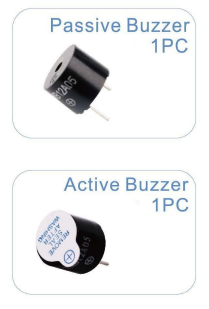

## 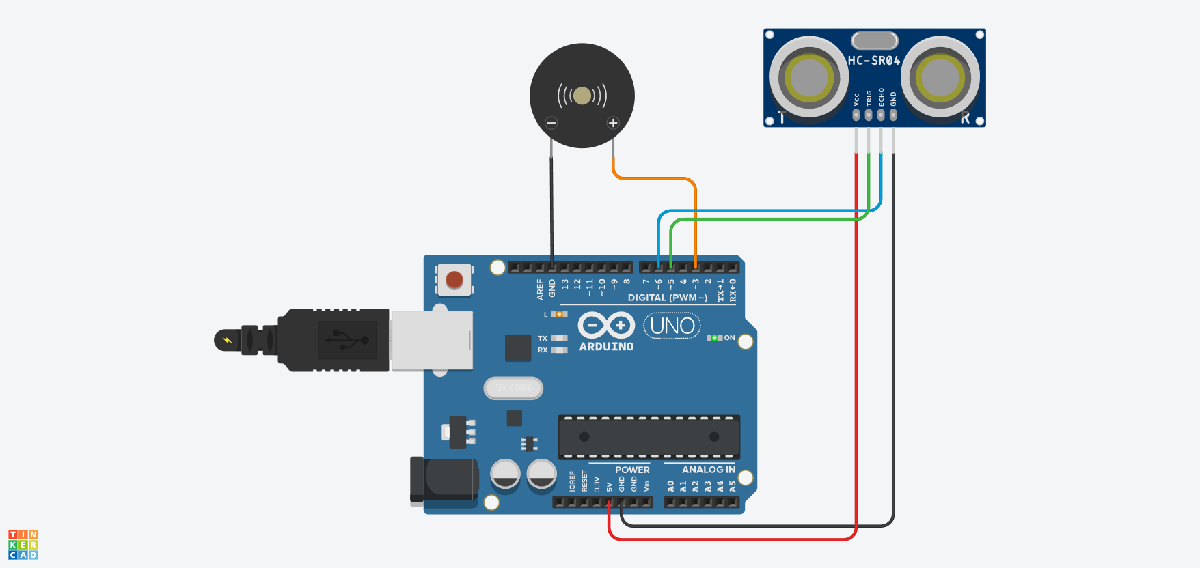

*Figure: PD Ultrasonic Buzzer*

This circuit figure above consists of a single passive buzzer and an ultrasonic sensor HC-SR04, be sure to use the passive buzzer or it may sound odd. The buzzer is a [piezoelectric crystal](https://en.wikipedia.org/wiki/Piezoelectric_speaker) that expands when a voltage is applied. This results in creating sound waves for us to hear. To simplify connecting everything you can use the Female to Male DuPont wires ([Picture link](https://webshop.clevercircuits.com/wp-content/uploads/2018/08/40pcs-dupont-wire-jumpercables-21cm-255mm-female-to-male-for-arduino.png)) in your kit and skip the breadboard. 

#### 2) Once your circuit is assembled, run the following code. Once you start the program, move an object towards or away from the ultrasonic sensor. Something flat and dense works great, like a book! How well does the sensor collect accurate data?

% PD2_2_Sensor_Measurement_Tutorial.mlx
% Date: 10/27/2024 

clear
clc
close all

% The circuit requires a passive buzzer on pin D3 and an ultrasonic sensor
% with trig on pin D5 and echo on pin D6

% Connect to Arduino and add library
hardwareTable = arduinolist;
arduino = arduino(hardwareTable{1, 1}, hardwareTable{1, 2}, 'Libraries', 'Ultrasonic');
ultrasonic = ultrasonic(arduino, 'D5', 'D6'); % Define to ultrasonic sensor
arduino.configurePin("D4", "Pullup")

% Variables
BUILT_IN_LED = "D13";
time = [];                  % Store time data
distance = [];           % Store distance data
note = ["C", "D", "E", "F", "G", "A", "B", "C5"]; % C major
%note = ["C", "D", "Eb", "E", "G", "A", "C5"]; % C major blues

range = .75;
line = animatedline(0, 0, "LineStyle", "none", "Marker", "*");

disp("Start") 

Start


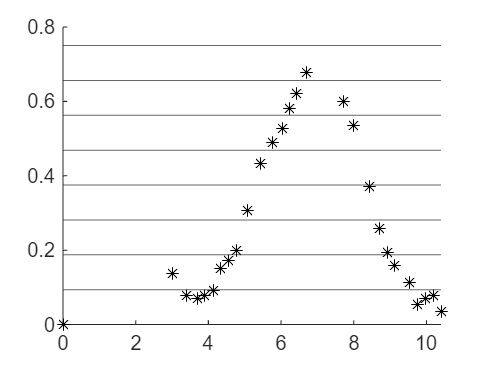

writeDigitalPin(arduino, BUILT_IN_LED, 0); % Turn off built in led to show code is running

tic(); % Start a timer for measuring

for i = 1:length(note)
    yline(((i*1.)/length(note))*range)
end
hold on

i = 1;
while (arduino.readDigitalPin("D4"))
    distance = readDistance(ultrasonic);

    if (distance < range)
        input = distance / range;
        playTone(arduino, 'D3', f(note(floor(input * length(note)) + 1)), .5);

        addpoints(line, toc(), distance);
        drawnow
        data(i) = distance; % Record data
        i = i + 1;
    end
end



fprintf("Average: %f", mean(data))

Average: 0.272268



function frequency = f(s)
    % A function to give the frequency in Hz of a note from a string input
    % such as "A4" or "B#2" or "Eb5" if no octave is given, the function
    % will defualt to octave 4. This function will also accept vectors.
    % by Edison Bregger 10/22/2024

    % Set an easily changeable octave to defualt to if none is given 
    defualtOctave = 4;

    % Define size of final vector
    frequency = zeros(1, length(s), "double");

    % Loop through all strings
    for i = 1:length(s)

        % Get the string in all lower case at i
        input = convertStringsToChars(lower(s(i)));

        % Convert to note number
        switch input(1)
            case 'c'
                note = 1;
            case 'd'
                note = 3;
            case 'e'
                note = 5;
            case 'f'
                note = 6;
            case 'g'
                note = 8;
            case 'a'
                note = 10;
            case 'b'
                note = 12;
        end
    
        % Make sure an octave is specified
        if (length(input) > 1)

            % If a note is sharp or flat, modify the note number by 1
            % Also store the octave here because we know how long the array is
            if (input(2) == '#') % If sharp
                note = note + 1;
                if (length(input) > 2)
                    octave = str2double(input(3));
                else
                    octave = defualtOctave;
                end
            elseif (input(2) == 'b') % If flat
                note = note - 1;
                if (length(input) > 2)
                    octave = str2double(input(3));
                else
                    octave = defualtOctave;
                end
            else % If natural
                octave = str2double(input(2));
            end
        else
            octave = defualtOctave;
        end
    
        % n = notes away from A4
        n = note + (12 * octave) - 58; % A4 is 58 without the subtraction
        
        % Frequency can be found using n and this formula
        frequency(i) = 440 * 2^(n/12);
    end
end


Any Errors? (No Problem! Try These Steps)

- Is your Arudino Plugged in to the USB Port and LED lights are on?

- Head back and review the directions to figure out if anywhere overlooked.

- Check which pins your wires connect to, Also check that you have a good connection between wires. 

The desired effect is that when the distance sensor reads in different values, it will change notes played